tiqu = readtable('tiqu.csv')

tiqu = 68×9 table
    Num     x2      x3    x4    temp    water    x7     y1      y2 
    ___    _____    __    __    ____    _____    ___    ___    ____

     3     30.17    35    30     75     6360     187      6    5.36
     2     32.14    35    25     80     6360     187      7    8.32
     1     31.66    35    27     75     6360     187    6.5    7.18
     3     29.35    35    30     71     6360     187      6    5.17
     1     29.29    35    33     71     6360     187    5.5    5.66
     2     28.75    35    35     65     6360     187    4.5    4.78
     1      30.1    35    30     72     6360     187    5.5    5.81
     3     29.18    35    33     65     6360     187    5.5    

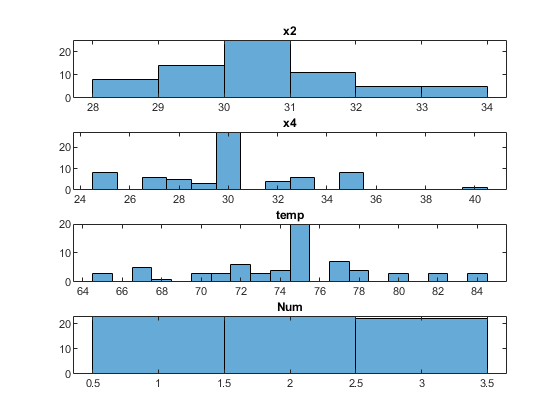

subplot(4,1,1)
histogram(tiqu{:,"x2"});
title("x2");
% x4
subplot(4,1,2)
histogram(tiqu{:,"x4"});
title("x4");
%temp
subplot(4,1,3)
histogram(tiqu{:,"temp"});
title("temp");

subplot(4,1,4)
histogram(tiqu{:,"Num"});
title("Num");

SampleNum = 300;
sz = [SampleNum,1];

## gen fake stream

Num = randi(3,sz);
% norm fit
[mu,sigma] = normfit(tiqu{:,"x2"});
x2 = normrnd(mu,sigma,sz);
Counts = tabulate(tiqu{:,'x4'});
noZeroIndex = Counts(:,2)>0;
s = RandStream('mlfg6331_64'); 
x4 = datasample(s,Counts(noZeroIndex,1),SampleNum,'Weights',Counts(noZeroIndex,3));

Counts = tabulate(tiqu{:,'temp'});
noZeroIndex = Counts(:,2)>0;
temp = datasample(s,Counts(noZeroIndex,1),SampleNum,'Weights',Counts(noZeroIndex,3));
% 新建一个空的dataFrame
types = {'double','double','double','double','double','double','double'};
names = tiqu.Properties.VariableNames(1:7);
fake_Gen = table('Size',[SampleNum,7],'VariableTypes',types,'VariableNames',names);
%%
fake_Gen{:,"x3"} = 35*ones(sz);
fake_Gen{:,"water"} = 6360*ones(sz);
fake_Gen{:,"x7"} = 187*ones(sz);

fake_Gen{:,"Num"} = Num;
fake_Gen{:,"x2"} = x2;
fake_Gen{:,"temp"} = temp;
fake_Gen{:,"x4"} = x4;
fake_Gen

fake_Gen = 300×7 table
    Num      x2      x3    x4    temp    water    x7 
    ___    ______    __    __    ____    _____    ___

     2     30.754    35    30     75     6360     187
     2     28.538    35    32     73     6360     187
     1     31.149    35    30     65     6360     187
     1     30.713    35    30     67     6360     187
     1     29.825    35    32     73     6360     187
     1     31.228    35    30     75     6360     187
     2     29.644    35    32     74     6360     187
     1     28.799    35    30     75     6360     187
     3     28.263    35    25     75     6360     187
     2     30.098    35    25     80     6360     187
     1      29.75    35    30     67     6360     187
     1     31.158    35    33     70

writetable(fake_Gen,"Gendata.csv")